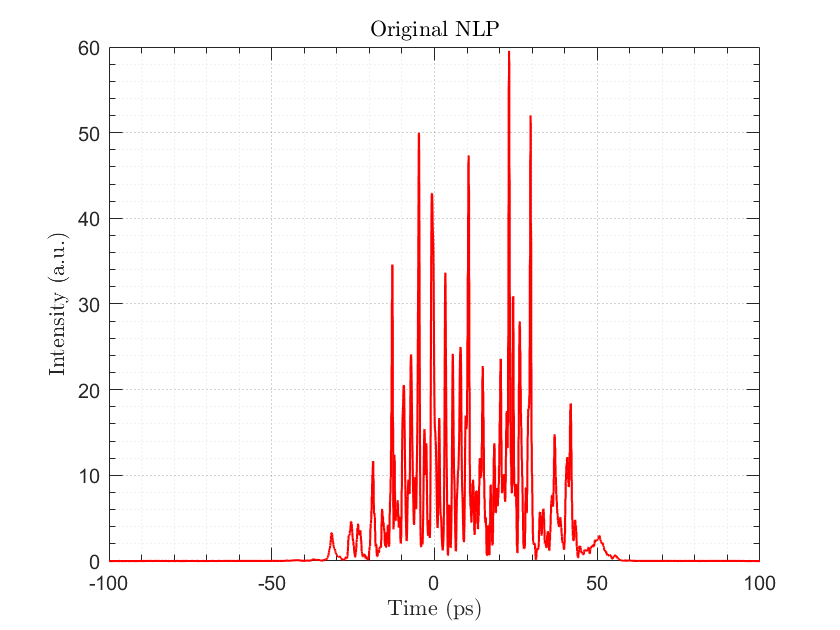

clear
clf
close all 
cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

% ============= NLP Data =============== %
nlpulse = readmatrix("Pulse.txt");
t_ps = nlpulse(:,1)*1e12;

E_N = nlpulse(:,2) + 1j*nlpulse(:,3); 
E_P = nlpulse(:,4) + 1j*nlpulse(:,5);

I_T = abs(E_P).^2 + abs(E_N).^2;

% ====================================== %

% ============= Linear scale plots =============== %
plot(t_ps,I_T, "Color", [1 0 0], 'LineWidth', 1.05)
title('Original NLP',"Interpreter","latex");
xlabel('Time (ps)', "Interpreter","latex");
ylabel('Intensity (a.u.)',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
hold off

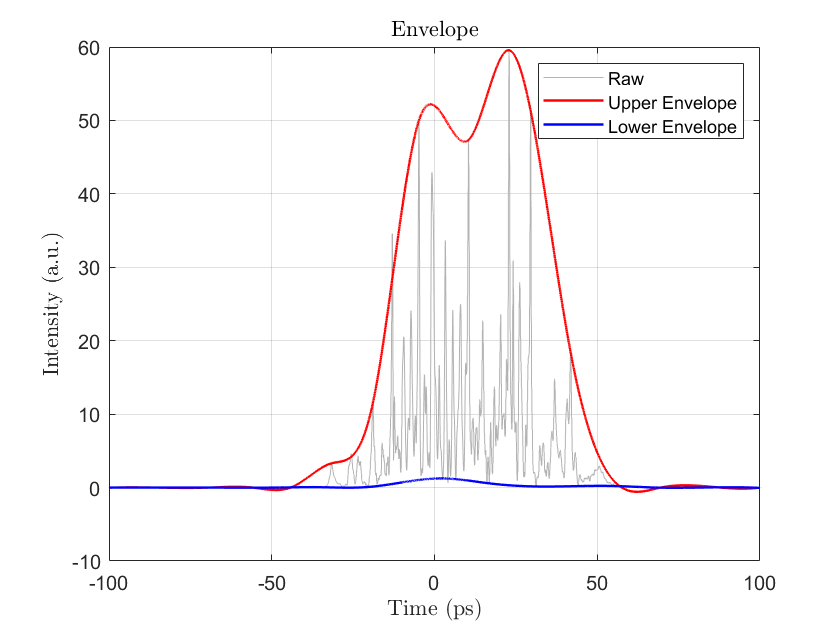


% ===================== Envelope =================%
% Choose windowSize to match your time resolution
windowSize = 990;  
[upper_env, lower_env] = envelope(I_T, windowSize, 'peak');

figure;
plot(t_ps, I_T, 'Color',[0.7 0.7 0.7]); hold on
plot(t_ps, upper_env, 'r', 'LineWidth',1.2);
plot(t_ps, lower_env, 'b', 'LineWidth',1.2);
legend('Raw','Upper Envelope','Lower Envelope');
xlabel('Time (ps)','Interpreter','latex');
ylabel('Intensity (a.u.)','Interpreter','latex');
title('Envelope','Interpreter','latex');
grid on; box on;

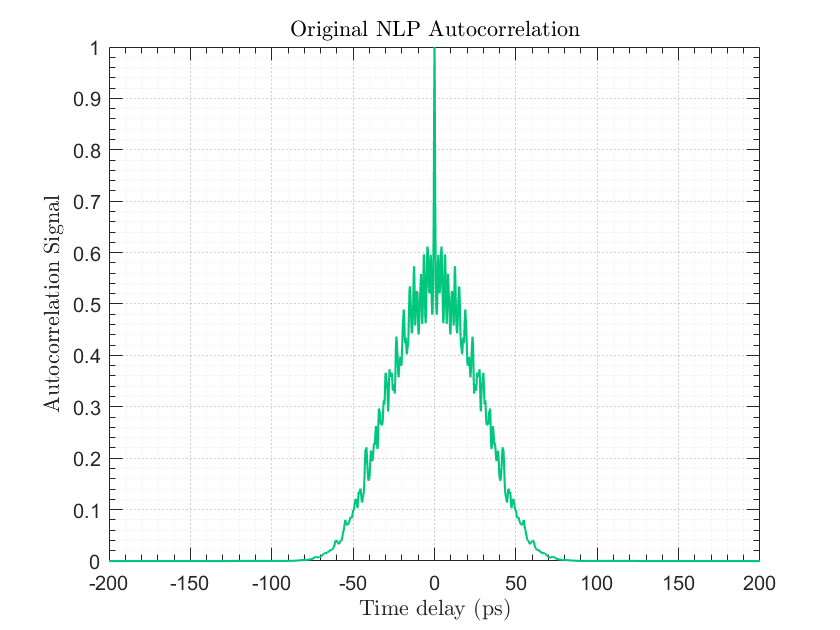



% =============== Auto correlation ================== %
% Compute the sample‐spacing (in ps) lags → time:
dt = mean(diff(t_ps));  

% Compute autocorrelation:
[acf, lags] = xcorr(I_T, 'coeff');  

% Convert lag indices to physical lag times (in ps):
lags_time = lags * dt;  

%Plot:
figure()
plot(lags_time, acf, 'LineWidth', 1.05, 'Color', '#00c77d');
xlabel('Time delay (ps)', 'Interpreter','latex');
ylabel('Autocorrelation Signal', 'Interpreter','latex');
title('Original NLP Autocorrelation', 'Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

% ============= New NLP's =============== %
M = 50; % Number of new pulses
sigma = 2.34; % Amplitude variation
mu = 4.89; % Amplitude variation
delta_t = 1.5; % Temporal position randomness
[NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, delta_t, 'shuffle');

dt = mean(diff(t_ps));       % sample spacing in ps

for i = 1:M
    fname = sprintf('NLPx%d.csv', i);
    SvNLP = [t_ps, NLP_Neg(:,i), NLP_Pos(:,i)];
    writematrix(SvNLP, fname)
end
% =========================================== %


function [NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, delta_t, seed)
    arguments
        E_P (:,1)  {mustBeNumeric}
        E_N (:,1)  {mustBeNumeric}
        sigma (1,1) double
        mu    (1,1) double
        M     (1,1) {mustBeInteger,mustBePositive}
        t_ps  (:,1) double = (0:numel(E_P)-1).'   
        delta_t (1,1) double = 0.1  % Temporal shift intensity control
        seed  double = NaN
    end
    
    if ~isnan(seed)          
        if isequal(seed,'shuffle')
            rng('shuffle');
        else
            rng(seed);     
        end
    end
    
    % Pre-allocate
    N  = numel(E_P);
    NLP_Pos = zeros(N, M);
    NLP_Neg = zeros(N, M);

    %% NLP Generation
    for k = 1:M
        % ------------ Random gain factor -------------- (amplitude variation)
        g_k = sigma * rand(N,1) + mu;

        % ------------ Random time shift -------------- (temporal variation)
        % Apply random time shift within the bounds
        time_shift = round(delta_t * (rand() - 0.5));  % Random shift within [-delta_t/2, delta_t/2]

        % ------------ Apply time shift to the pulses --------------------
        % Shift the pulses within the bounds of the time vector
        % Ensure no out-of-bound errors when shifting the signal
        if time_shift > 0
            NLP_Pos(:,k) = [zeros(time_shift, 1); E_P(1:end-time_shift) .* g_k];  % Shifted positive pulse
            NLP_Neg(:,k) = [zeros(time_shift, 1); E_N(1:end-time_shift) .* g_k];  % Shifted negative pulse
        elseif time_shift < 0
            NLP_Pos(:,k) = [E_P(-time_shift+1:end) .* g_k; zeros(-time_shift, 1)];  % Shifted positive pulse
            NLP_Neg(:,k) = [E_N(-time_shift+1:end) .* g_k; zeros(-time_shift, 1)];  % Shifted negative pulse
        else
            NLP_Pos(:,k) = E_P .* g_k;  % No shift, just apply the gain factor
            NLP_Neg(:,k) = E_N .* g_k;  % No shift, just apply the gain factor
        end

        % Ensure that the shift did not result in NaN values
        NLP_Pos(isnan(NLP_Pos(:,k)), k) = 0;
        NLP_Neg(isnan(NLP_Neg(:,k)), k) = 0;
    end
end
